## Two-cart and spring system

This example loosely follows along with the Mathworks example "Building and Manipulating Uncertain Models"

[https://www.mathworks.com/help/robust/examples/building-and-manipulating-uncertain-models.html](https://www.mathworks.com/help/robust/examples/building-and-manipulating-uncertain-models.html) 

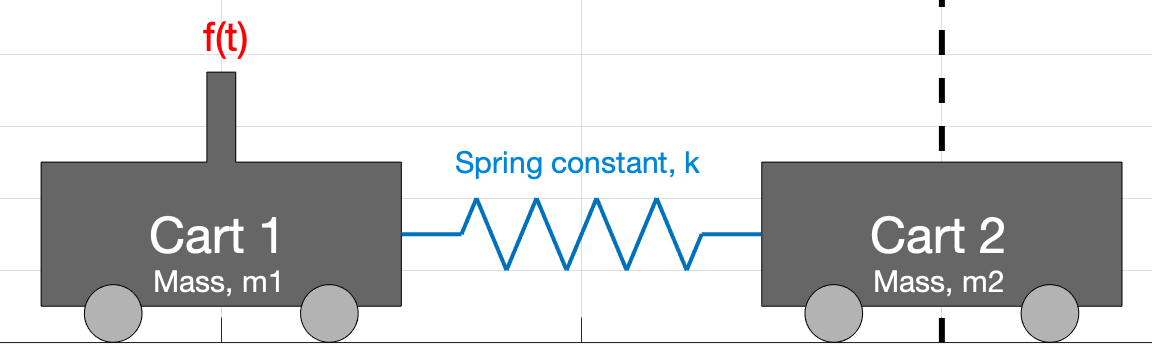

### Visualization

spring_carts_visualize

Current plot held


### State space model


$$A=\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{k}{m_1 } & 0 & \frac{k}{m_1 } & 0\\
0 & 0 & 0 & 1\\
\frac{k}{m_2 } & 0 & -\frac{k}{m_2 } & 0
\end{array}\right\rbrack$$
   
$$B=\left\lbrack \begin{array}{c}
0\\
\frac{1}{m_1 }\\
0\\
0
\end{array}\right\rbrack$$
   
$$C=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$
   
$$D=\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


### State vector


$$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\textrm{Position}}_{\textrm{cart}1} \\
{\textrm{Velocity}}_{\textrm{cart}1} \\
{\textrm{Position}}_{\textrm{cart2}} \\
{\textrm{Velocity}}_{\textrm{cart2}} 
\end{array}\right\rbrack$$


### Buid a model of the system

% Set parameters
k = 1;
m1 = 1;
m2 = 1;

% Build state space model
A = [ 0,     1,   0,     0; 
     -k/m1,  0,   k/m1,  0; 
      0,     0,   0,     1; 
      k/m2,  0,  -k/m2,  0];
  
B = [0; 1/m1; 0; 0];

C = eye(4);

D = [0;0;0;0];

G = ss(A, B, C, D);

### Design an LQR controller

See LQR MATLAB Tech Talks for more information - link is in the description

% LQR controller
Q = [1 0 0 0;
     0 1 0 0;
     0 0 10 0;
     0 0 0 20];
R = 7;

K = lqr(G, Q, R); % Full state feedback gains

% Closed loop system
Gcl = feedback(G*K, eye(4));

### Plot closed loop response

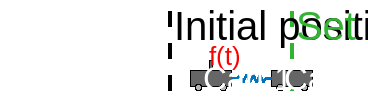

T = 0:0.01:30; % Time vector
U = ones(size(T'))*[1 0 1 0]; % Input 
lsim(Gcl, U, T);

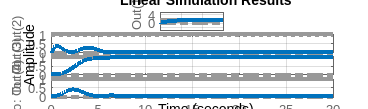

grid on
set(findall(gcf,'type','line'),'linewidth',3);

### Will the controller work on the hardware?

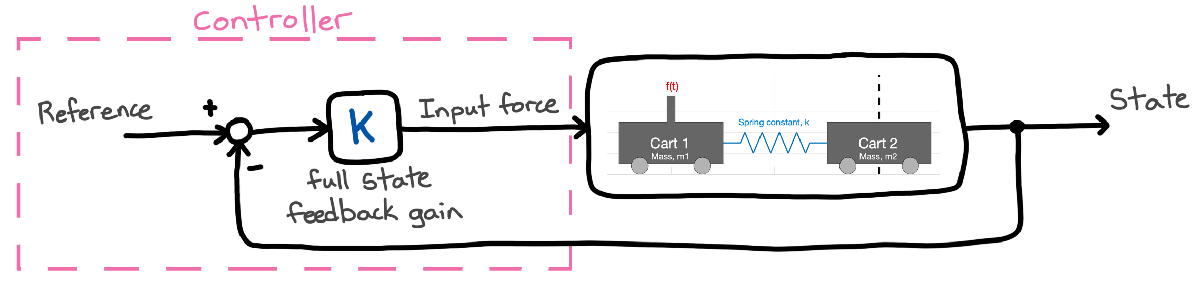

% Look at disk margin
MMIO = diskmargin(K, G)

MMIO = struct with fields:
           GainMargin: [0.7617 1.3129]
          PhaseMargin: [-15.4070 15.4070]
           DiskMargin: 0.2705
           LowerBound: 0.2705
           UpperBound: 0.2711
            Frequency: 1.7124
    WorstPerturbation: [1×1 struct]


### Build a model with uncertain parameters

k = ureal('k',1,'percent',30);   
m1 = ureal('m1',1,'percent',10); 
m2 = ureal('m2',1,'percent',20); 

% Build uncertain state space model
A = [ 0,     1,   0,     0; 
     -k/m1,  0,   k/m1,  0; 
      0,     0,   0,     1; 
      k/m2,  0,  -k/m2,  0];
B = [0; 1/m1; 0; 0];
C = eye(4);
D = [0;0;0;0];
Gunc = ss(A, B, C, D)

Gunc =

  Uncertain continuous-time state-space model with 4 outputs, 1 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    k: Uncertain real, nominal = 1, variability = [-30,30]%, 2 occurrences
    m1: Uncertain real, nominal = 1, variability = [-10,10]%, 2 occurrences
    m2: Uncertain real, nominal = 1, variability = [-20,20]%, 1 occurrences

Type "Gunc.NominalValue" to see the nominal value, "get(Gunc)" to see all properties, and "Gunc.Uncertainty" to interact with the uncertain elements.



### Use controller with the uncertain system

% Uncertain closed loop system
Gcl = feedback(Gunc*K, eye(4));

% Check robust stability margins for the uncertain system
opt = robOptions('Display','on','Sensitivity','on');
[StabilityMargin,wcu] = robstab(Gcl,opt);

Computing peak...  Percent completed: 100/100
System is robustly stable for the modeled uncertainty.
 -- It can tolerate up to 230% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 230% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 2.35 rad/seconds.
 -- Sensitivity with respect to each uncertain element is:           
      5% for k. Increasing k by 25% decreases the margin by 1.25%.   
      7% for m1. Increasing m1 by 25% decreases the margin by 1.75%. 
      70% for m2. Increasing m2 by 25% decreases the margin by 17.5%.


% Smallest destabilizing parameter variation
wcu

wcu = struct with fields:
     k: 1.6858
    m1: 1.2302
    m2: 0.5396


% Build closed loop model with unstable parameters
wcu.m2 = wcu.m2 * 0.95;
Gclw = usubs(Gcl, wcu);

### Step response for uncertain system

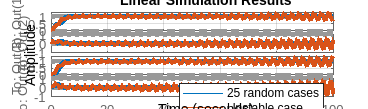

T = 0:0.01:100; % Time vector
U = ones(size(T'))*[1 0 1 0]; % Input 
lsim(Gcl, U, T);
grid on
hold all
lsim(Gclw, U, T);
legend('25 random cases', 'Unstable case');
set(findall(gcf,'type','line'),'linewidth',3);

### Gain and phase uncertainty + parameter uncertainty

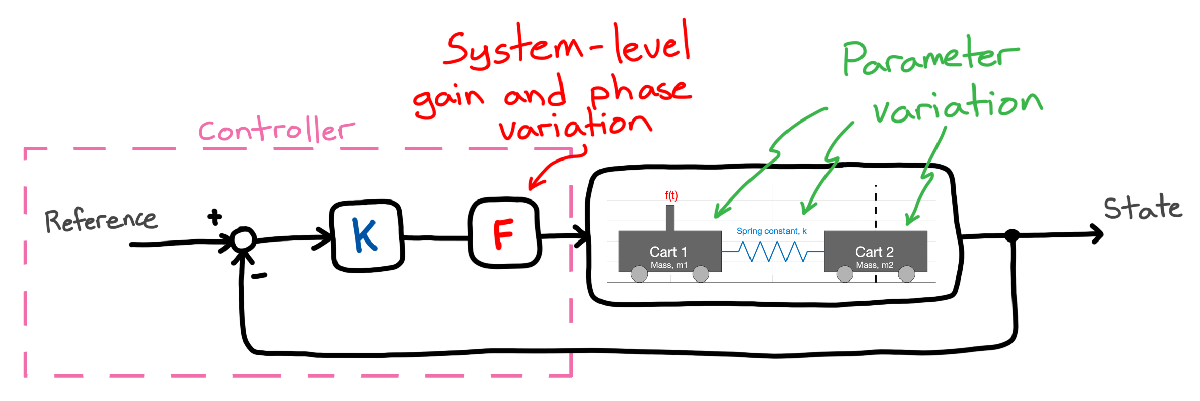

GMargin = [0.9 1.1]; % Gain varation 0.9 - 1.1 and 
PMargin = [-15 15]; % Phase variation +/- 15 deg
DGM = getDGM(GMargin,PMargin,'tight'); % Gain varation for the above two
F = umargin('DGM', DGM);
Gcl = feedback(Gunc*K*F, eye(4)); % Uncertain feedback system
[StabMar,wcu] = robstab(Gcl,opt); % Robust stability margins

Computing peak...  Percent completed: 100/100
System is robustly stable for the modeled uncertainty.
 -- It can tolerate up to 147% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 147% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 2.03 rad/seconds.
 -- Sensitivity with respect to each uncertain element is:             
      49% for DGM. Increasing DGM by 25% decreases the margin by 12.2%.
      3% for k. Increasing k by 25% decreases the margin by 0.75%.     
      11% for m1. Increasing m1 by 25% decreases the margin by 2.75%.  
      32% for m2. Increasing m2 by 25% decreases the margin by 8%.     


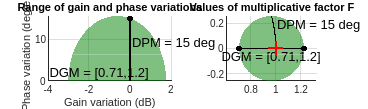

plot(F)